% Jared Steffen
% SID: 104654948
% ASEN 2803
% Date Created: 1/24/2023
% Date Modified:
%
% Lab 1: Rollercoaster 
%
% Objectives: 
%
% -Design a rollercoaster with a loop, 0G parabola,
%  banked turn, braking section, and smooth transitions between all.
% -Determine G-Forces acting throughout rollercoaster.
% -Plot velocity along length of coaster.
%
% Assumptions:
% 
% -Treat rollercoaster cart as a point mass.
% -Neglect drag (always) and friction (except in braking section)
% -Initial velocity is zero
%
% Constraints:
%
% -Max track length: 1250m
% -Upwards G's < 6
% -Downwards G's < 1
% -Forwards G's < 5
% -Backwards G's < 4
% -Lateral G's < 3
%------------------------------------------------------------------------------

% House Cleaning
clc
close all

% Initial Conditions
h0 = 125; % [m]
x0 = 0; % [m]
y0 = 100; % [m]
g = 9.81; % [m/s^2]

% Ramp
[h1,x1,y1,vel1,G1] = ramp(h0,x0,y0,40,50,g);

% Transition Out of Ramp, Into Loop (Curve)
[h2,x2,y2,vel2,G2,arc_length_trans1] = transition_curve(h0,h1(end),x1(end),y1(end),40,40,g);

% Loop
[h3,x3,y3,vel3,G3,arc_length_loop] = loop(h0,h2(end),x2(end),y2(end),17,g);

% Transition Out Of Loop, Into Banked Turn (Straight Line)
[h4,x4,y4,vel4,G4] = transition_line(h0,h3(end),x3(end),y3(end),50,g);

% Banked Turn
[h5,x5,y5,vel5,lat_G5,vert_G5,arc_length_banked] = banked_turn(h0,h4(end),x4(end),y4(end),45,40,g);

% Loop
[h6,x6,y6,vel6,G6,arc_length_loop2] = loop(h0,h5(end),x5(end),y5(end),17,g);

% Transition Out of Loop, Into ___ (Straight Line)
[h7,x7,y7,vel7,G7] = transition_line_reverse(h0,h6(end),x6(end),y6(end),30,g);


% Verify Total Track Length is Within Range
Track_Length = 50 + arc_length_trans1 + arc_length_loop + 50 + arc_length_banked...
    + arc_length_loop2 + 30

Track_Length = 497.2173


% Verify G's Are Within Acceptable Ranges
% Ramp - Vertical G's
maxG1 = max(G1)

maxG1 = 0.7660


% Transition 1 - Vertical G's
maxG2 = max(G2)

maxG2 = 1


% Loop - Vertical G's
maxG3 = max(G3)

maxG3 = 5.8821


% Transition 2 - Vertical G's
maxG4 = max(G4)

maxG4 = 1


% Banked Turn - Vertical and Lateral G's
maxG5_lat = max(lat_G5)

maxG5_lat = 0.3303

maxG5_vert = max(vert_G5)

maxG5_vert = 2.1743


% Loop 2 - Vertical G's
maxG6 = max(G6)

maxG6 = 5.8821


% Transition 3 - Vertical G's
maxG7 = max(G7)

maxG7 = 1

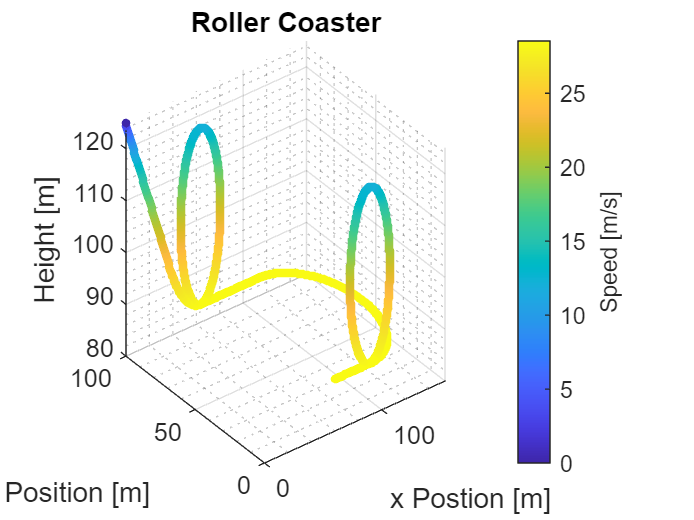



% Put Together Plotting Vectors
x_pos = [x1,x2,x3,x4,x5,x6,x7];
y_pos = [y1,y2,y3,y4,y5,y6,y7];
h_pos = [h1,h2,h3,h4,h5,h6,h7];
vel_whole_track = [vel1,vel2,vel3,vel4,vel5,vel6,vel7];

% Plot Rollercoaster
scatter3(x_pos,y_pos,h_pos,10,vel_whole_track,'filled')
hold on
grid on; grid minor
title('Roller Coaster')
c = colorbar;
c.Label.String = 'Speed [m/s]';
xlabel('x Postion [m]')
ylabel('y Position [m]')
zlabel('Height [m]')
hold off

function[h_current,x_current,y_current,vel,G_ramp] = ramp(h0,x,y,ramp_theta,ramp_length,g)

% Parameters
ramp_pos = (0:ramp_length);

% Current Positions
h_current = h0 - ramp_pos * sind(ramp_theta);
x_current = x + ramp_pos * cosd(ramp_theta);
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g * cosd(ramp_theta);

% G's Experienced
G_ramp = zeros(1,length(x_current));
G_ramp = G_ramp + N ./ g;

end

function[h_current,x_current,y_current,vel,G_trans1,arc_length] = transition_curve(h0,h,x,y,theta_1,R,g)

% Parameters
theta_range = (360 - theta_1:360);
arc_length = (theta_1 / 360) * 2 * pi * R;

% Current Positions
h_current = h + R * cosd(360 - theta_1) - R * cosd(theta_range);
x_current = x - R * sind(360 - theta_1) + R * sind(theta_range); 
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g * cosd(theta_range);

% G's Experienced 
G_trans1 = N ./ g;

end


function[h_current,x_current,y_current,vel,G_loop,circumference] = loop(h0,h,x,y,R,g)

% Parameters
circumference = 2 * pi * R; % [m]
theta_range = 0:360; % [^o]

% Current Positions
h_current = h + (R - R*cosd(theta_range));
x_current = x + R*sind(theta_range); 
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Acceleration for Normal Force
a_n = vel.^2/R;

% Normal Force
N = g * cosd(theta_range) + a_n;

% G's Experienced
G_loop = N ./ g;

end

function[h_current,x_current,y_current,vel,G_trans2] = transition_line(h0,h,x,y,track_length,g)

% Parameters
x_range = (0:track_length);

% Current Positions
x_current = x + x_range; 
h_current = h + zeros(1,length(x_current));
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g;

% G's Experienced
G_trans2 = zeros(1,length(x_current));
G_trans2 = G_trans2 + N / g;

end

function[h_current,x_current,y_current,vel,G_trans3] = transition_line_reverse(h0,h,x,y,track_length,g)

% Parameters
x_range = (0:track_length);

% Current Positions
x_current = x - x_range; 
h_current = h + zeros(1,length(x_current));
y_current = y + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Normal Force
N = g;

% G's Experienced
G_trans3 = zeros(1,length(x_current));
G_trans3 = G_trans3 + N / g;

end

function[h_current,x_current,y_current,vel,G_banked_lat,G_banked_vert,arc_length] = banked_turn(h0,h,x,y,bank_theta,R,g)

% Parameters
theta_range = (0:180);
arc_length = (180 / 360) * 2 * pi * R;

% Current Positions
x_current = x + R * sind(theta_range);
y_current = y - R + R * cosd(theta_range);
h_current = h + zeros(1,length(x_current));

% Velocity
vel = sqrt(2*g*(h0-h_current));

% Acceleration for Normal Force
a_n = vel.^2/R;

% Normal Force
N_vertical = g * cosd(bank_theta) + a_n * sind(bank_theta);
N_lateral = -sind(bank_theta) * (g - (a_n * cosd(bank_theta)));
 
% G's Experienced
G_banked_lat = zeros(1,length(x_current));
G_banked_vert = zeros(1,length(x_current));
G_banked_lat = G_banked_lat + N_lateral ./ g;
G_banked_vert = G_banked_vert + N_vertical ./ g;

end